**GRF Analysis**

The goal of this script is to analysis the relationship between 

addpath('../traj_opt_grf/');

human_model = '../human_8/';
humanExo_model= '../human_exo1/';

step1.human.base = load([human_model,'1228150554.mat']).result;
step1.human.hip = load([human_model,'1228150738.mat']).result;
step1.human.kne = load([human_model,'1228150732.mat']).result;
step1.human.ank = load([human_model,'1228151258.mat']).result;
step1.human.Hk = load([human_model,'1228150608.mat']).result;
step1.human.Ha = load([human_model,'1228150651.mat']).result;
step1.human.Ka = load([human_model,'1228150842.mat']).result;

step1.exo.base = load([humanExo_model,'1228144025.mat']).result;
step1.exo.hip = load([humanExo_model,'1228145354.mat']).result;
step1.exo.kne = load([humanExo_model,'1228144625.mat']).result;
step1.exo.ank = load([humanExo_model,'1228144620.mat']).result;
step1.exo.Hk = load([humanExo_model,'1228145444.mat']).result;
step1.exo.Ha = load([humanExo_model,'1228145121.mat']).result;
step1.exo.Ka = load([humanExo_model,'1228144534.mat']).result;


grf1 = biped_grf(step1.human.base.x,step1.human.base.param,human_model);
vel1 = biped_hipVel(step1.human.base.x,step1.human.base.param,human_model);
grf2 = biped_grf(step1.human.hip.x,step1.human.hip.param,human_model);
vel2 = biped_hipVel(step1.human.hip.x,step1.human.hip.param,human_model);

grf3 = biped_grf(step1.human.base.x,step1.human.base.param,human_model);
vel3 = biped_hipVel(step1.human.base.x,step1.human.base.param,human_model);
grf4 = biped_grf(step1.human.hip.x,step1.human.hip.param,human_model);
vel4 = biped_hipVel(step1.human.hip.x,step1.human.hip.param,human_model);


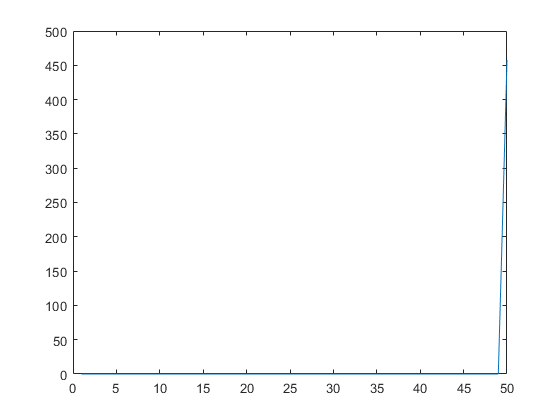

plot(grf1(4,:));